## Lecture 5

Notes:

For at finde gennemsnittet i Matlab kan man bruge: **mean**


$$\hat{\;\mu {\;}_x =\bar{\;X} =\frac{1}{n}\sum_{i=1}^n X_{i\;} }$$


standard afvigelse: std


$$s_x =+\sqrt{\;s_{x\;}^2 }$$


Histogram: **histogram(x, bins)**

hvor x er en vector og bins er antallet af bins.

Boxplot: **boxplot**


$$p=25%=q_{1\;} \;$$
    
$$25%\;\mathrm{fraktil}$$



$$p=50%=q_2 \;$$
    
$$\mathrm{median}$$



$$p=75%=q_{3\;} \;$$
    
$$75%\;\mathrm{fraktil}$$


Quantile: **qqplot**

Check af antaget af fordelingen.

Det tager fraktilerne fra to forskellige plots of plotter dem i forhold til hinanden. Hvis de ligger nogenlunde på linje, så er de gode.

Den teoretiske quantile er en **pdf** og data quantile er et **histogram**

format shortg

**6.1.1-5**

**6.1.1 Will the sample mean always correspond to one of the observations in the sample?**

No, the sample mean is the average value of all observations in the data set

If the sample is $\left\lbrace 2,3\right\rbrace$ the sample mean is $2\ldotp 5$ and that is not a sample.

**6.1.2 Will exactly half of the observations in a sample fall below the mean?**

Yes

**6.1.3 Will the sample mean always be the most frequently occurring data value in the sample?**

No, if the most occuring data is a low number. There might be 5 of these, but if the rest of the numbers are scattered in the higher end, the mean will not be one of the low most frequent numbers.

**6.1.4 For any set of data values, is it possible for the sample standard deviation to be larger than the sample mean? If so, give an example.**

Yes, we have the samples


$$\left\lbrace -1,1\right\rbrace$$


The mean is $\frac{1}{2}\cdot \left(-1\right)+\frac{1}{2}\cdot 1=0$

The sample deviation is $\frac{1}{2}\cdot {\left(-1-0\right)}^2 +\frac{1}{2}\cdot {\left(1-0\right)}^2 =1$

**6.1.5 Can the sample standard deviation be equal to zero? If so, give an example.**

The standard deviation will always be equal to zero. Which is why the value is squared to get only positive numbers.

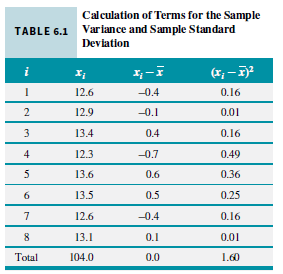

**6.1.9**

**An article in the Journal of Physiology [“Response of Rat Muscle to Acute Resistance Exercise Defined by Transcriptional and Translational Profiling” (2002, Vol. 545, pp. 27–41)] studied gene expression as a function of resistance exercise. **

**Expression data (measures of gene activity) from one gene are shown in the following table. One group of rats was exercised for 6 hours while the other received no exercise. Compute the sample mean and standard deviation of the exercise and no-exercise groups separately. Construct a dot diagram for the exercise and no-exercise groups separately. Comment on any differences for the groups.**


$$6\;\mathrm{hours}$$
         
$$\mathrm{No}\;\mathrm{Exercise}$$



$$223\ldotp 306$$
        
$$485\ldotp 396$$



$$388\ldotp 793$$
        
$$159\ldotp 471$$



$$139\ldotp 262$$
        
$$478\ldotp 314$$



$$212\ldotp 565$$
        
$$245\ldotp 782$$



$$325\ldotp 024$$
        
$$236\ldotp 212$$



$$208\ldotp 475$$
        
$$252\ldotp 773$$



$$286\ldotp 484$$
        
$$406\ldotp 921$$



$$244\ldotp 242$$
        
$$335\ldotp 209$$



$$408\ldotp 099$$



$$157\ldotp 743$$



$$436\ldotp 37$$


sixHours = [223.306 388.793 139.262 212.565 325.024 208.475 286.484 244.242 408.099 157.743 436.37]

sixHours =        223.31       388.79       139.26       212.56       325.02       208.47       286.48       244.24        408.1       157.74       436.37


noExercise = [485.396 159.471 478.312 245.782 236.212 252.773 406.921 335.209]

noExercise =         485.4       159.47       478.31       245.78       236.21       252.77       406.92       335.21


xbarSixHours = mean(sixHours)

xbarSixHours =        275.49


xbarNoExercise = mean(noExercise)

xbarNoExercise =        325.01


sigmaSixHours = std(sixHours)

sigmaSixHours =        101.71


sigmaNoExercise = std(noExercise)

sigmaNoExercise =         121.2



ySixHours = pdf("Normal",sixHours, xbarSixHours, sigmaSixHours)

ySixHours =     0.0034386     0.002109    0.0015996    0.0032392    0.0034836     0.003157    0.0038994    0.0037415    0.0016765     0.002007    0.0011227


yNoExercise = pdf("Normal", noExercise, xbarNoExercise, sigmaNoExercise)

yNoExercise =     0.0013713    0.0012951    0.0014791    0.0026584    0.0025168     0.002756    0.0026196      0.00328


Dot diagram should be made by hand to clearly illustrate if dots are placed on top of each other. So using a scatter is not a viable solution.

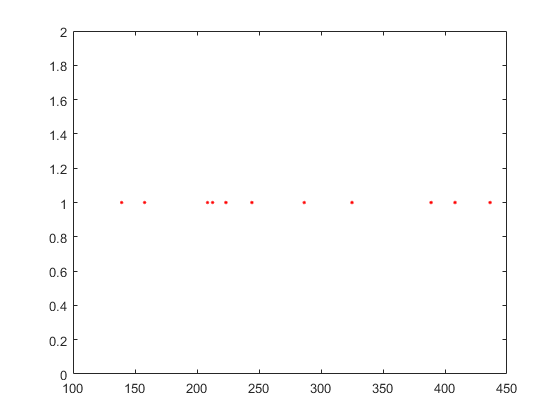

plot(sixHours, 1, 'r.');

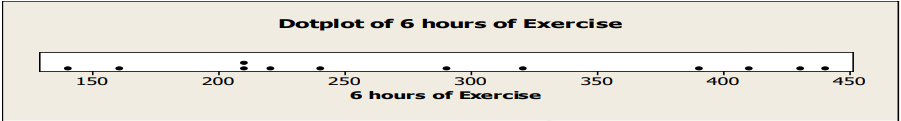

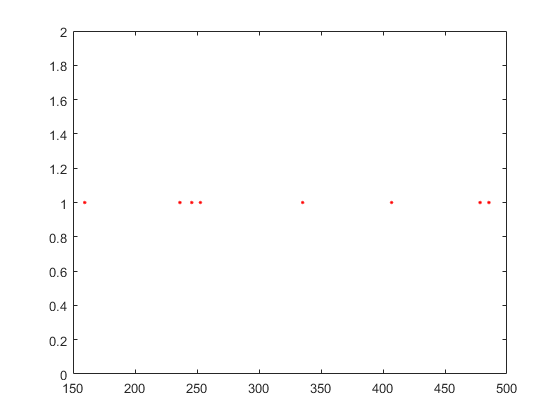

plot(noExercise, 1, 'r.');

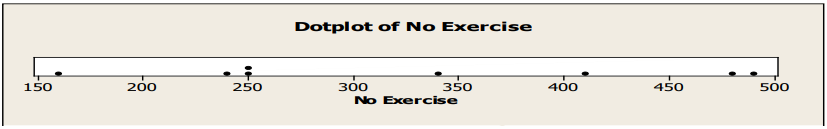

**6.1.12 **

**Cloud seeding, a process in which chemicals such as silver iodide and frozen carbon dioxide are introduced by aircraft into clouds to promote rainfall, was widely used in the 20th century. Recent research has questioned its effectiveness [“Reassessment of Rain Enhancement Experiments and Operations in Israel Including Synoptic Considerations,” Journal of Atmospheric Research (2010, Vol. 97(4), pp. 513–525)]. An experiment was performed by randomly assigning 52 clouds to be seeded or not. The amount of rain generated was then measured in acre-feet. Here are the data for the unseeded and seeded clouds:**

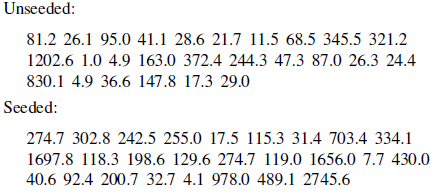

**Find the sample mean, sample standard deviation, and range of rainfall for**

unseeded = [81.2 26.1 95.0 41.1 28.6 21.7 11.5 68.5 345.5 321.2 1202.6 1.0 4.9 163.0 372.4 244.3 47.3 87.0 26.3 24.4 830.1 4.9 36.6 147.8 17.3 29.0]

unseeded =          81.2         26.1           95         41.1         28.6         21.7         11.5         68.5        345.5        321.2       1202.6            1          4.9          163        372.4        244.3         47.3           87         26.3         24.4        830.1          4.9         36.6        147.8         17.3           29


seeded = [274.7 302.8 242.5 255.0 17.5 115.3 31.4 703.4 334.1 1697.8 118.3 198.6 129.6 274.7 119.0 1656.0 7.7 430.0 40.6 92.4 200.7 32.7 4.1 978.0 489.1 2745.6]

seeded =         274.7        302.8        242.5          255         17.5        115.3         31.4        703.4        334.1       1697.8        118.3        198.6        129.6        274.7          119         1656          7.7          430         40.6         92.4        200.7         32.7          4.1          978        489.1       2745.6


**a. All 52 clouds**

xBarTotal= mean([unseeded seeded])

xBarTotal =        303.29


sigmaTotal= std([unseeded seeded])

sigmaTotal =           515


rangeTotal = max([unseeded seeded]) - min([unseeded seeded])

rangeTotal =        2744.6


**b. The unseeded clouds**

xBarUnseeded = mean(unseeded)

xBarUnseeded =        164.59


sigmaUnseeded = std(unseeded)

sigmaUnseeded =        278.43


rangeUnseeded = max(unseeded) - min(unseeded)

rangeUnseeded =        1201.6


**c. The seeded clouds**

xBarSeeded = mean(seeded)

xBarSeeded =        441.98


sigmaSeeded = std(seeded)

sigmaSeeded =        650.79


rangeSeeded = max(seeded) - min(seeded)

rangeSeeded =        2741.5


**6.3.3**

**Construct histograms with 8 and 16 bins for the data in Exercise 6.2.5. Compare the histograms. Do both histograms**

**display similar information?**

**fra 6.2.5**

**The following data are the numbers**

**of cycles to failure of aluminum test coupons subjected to**

**repeated alternating stress at 21,000 psi, 18 cycles per second.**

**1115 865 1015 885 1594 1000 1416 1501**

**1310 2130 845 1223 2023 1820 1560 1238**

**1540 1421 1674 375 1315 1940 1055 990**

**1502 1109 1016 2265 1269 1120 1764 1468**

**1258 1481 1102 1910 1260 910 1330 1512**

**1315 1567 1605 1018 1888 1730 1608 1750**

**1085 1883 706 1452 1782 1102 1535 1642**

**798 1203 2215 1890 1522 1578 1781**

**1020 1270 785 2100 1792 758 1750**

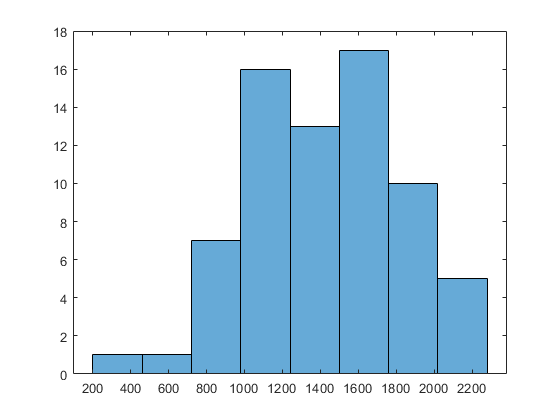

x = [1115 865 1015 885 1594 1000 1416 1501 1310 2130 845 1223 2023 1820 1560 1238 1540 1421 1674 375 1315 1940 1055 990 1502 1109 1016 2265 1269 1120 1764 1468 1258 1481 1102 1910 1260 910 1330 1512 1315 1567 1605 1018 1888 1730 1608 1750 1085 1883 706 1452 1782 1102 1535 1642 798 1203 2215 1890 1522 1578 1781 1020 1270 785 2100 1792 758 1750];
histogram(x,8)

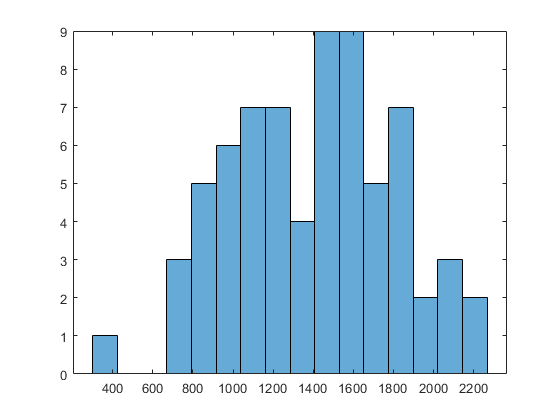

histogram(x,16)

**6.4.1**

**Using the data from Exercise 6.1.12 on cloud seeding, **

**a. Find the median and quartiles for the unseeded cloud data. (Median is 50%)**

q_unseed = quantile(unseeded, [0 0.25 0.5 0.75 1])

q_unseed =             1         24.4         44.2          163       1202.6


**b. Find the median and quartiles for the seeded cloud data.**

q_seed = quantile(seeded, [0 0.25 0.5 0.75 1])

q_seed =           4.1         92.4        221.6          430       2745.6


**c. Make two side-by-side box plots, one for each group on the same plot.**

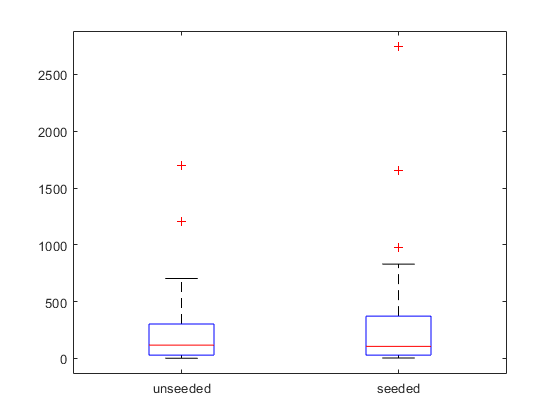

group = [ones(size(unseeded'));
         2* ones(size(seeded'))];
figure
boxplot([unseeded; seeded], group)
set(gca, 'XTicklabel',{'unseeded','seeded'})

**d. Compare the distributions from what you can see in the side-by-side box plots.**

The seeded plot has more far out values that are not evaluated by the boxplot.

Therefore the values evaluated in the unseeded is smaller and probably more correct.

The median is also closer to the center of the boxplot than in the seeded.

**6.7.2**

**Construct a normal probability plot of the octane rating data in Exercise 6.2.4. Does it seem reasonable to assume that octane rating is normally distributed?**

**7.2.4**

**Suppose that the random variable X has the continuous uniform distribution**


$$f\left(x\right)=\left\lbrace \begin{array}{ll}
1 & 0\le x\le 1\\
0 & \mathrm{otherwise}
\end{array}\right.$$


**Suppose that a random sample of n = 12 observations is selected from this distribution. What is the approximate probability distribution of **$X-6$**? **

**Find the mean and variance of this quantity.**

**7.3.2**

**Suppose we have a random sample of size 2n from a population denoted by **$X$**, and **$E\left(X\right)=\mu \;$ **and **$V\left(X\right)=\sigma^2$**. Let **


$$\bar{\;X_1 } =\frac{1}{2n}\sum_{i=1}^{2n} X_i$$
    
$$\mathrm{and}$$
     
$$\bar{\;X_2 } =\frac{1}{n}\sum_{i=1}^n X_i$$


**be two estimators of **$\mu$**.Which is the better estimator of **$\mu$**? Explain your choice.**

**7.4.1**

**Let X be a geometric random variable with parameter p. Find the maximum likelihood estimator of p based on a random sample of size n.**


$$P\left(\theta \;|D\right)=\frac{P\left(D|\theta \;\right)P\left(\theta \;\right)}{p\left(D\right)}$$



$$D=X_1 \cap X_{2\;} \cap \ldotp \ldotp \ldotp \cap X_n$$



$$P\left(D|\theta \;\right)=P\left(X_1 |\theta \;\right)\ldotp \ldotp \ldotp P\left(X_n |\theta \;\right)$$


             
$$=f\left(x_1 ,\theta \;\right)\ldotp \ldotp \ldotp f\left(x_n ,\theta \;\right)$$


             
$$=L\left(\theta \;\right)$$



$$\frac{\partial L\left(p\right)}{\partial p\;}=0\Leftrightarrow \frac{\partial L\left(\hat{p} \right)}{\partial p\;}=0$$



$$L\left(p\right)=\prod_{i=1}^n f\left(x_i ,p\right)$$



$$\mathrm{lnL}\left(p\right)=\sum_{i=1}^n \mathrm{ln}\left(f\left(x_i ,p\right)\right)$$


Geometrisk fordeling: $f\left(x,p\right)={\left(1-p\right)}^{x-1} p$

skriv likelihood funktion op


$$L\left(p\right)=\prod_{i=1}^n f\left(x_i ,p\right)=\prod_{i=1}^n {\left(1-p\right)}^{x_i -1} p=p^n \cdot \;\prod_{i=1}^n {\left(1-p\right)}^{x_i -1} ={\left(\frac{p}{1-p}\right)}^n \cdot \;\prod_{i=1}^n {\left(1-p\right)}^{x_i }$$


tager ln af den


$$\mathrm{lnL}\left(p\right)=n\cdot \left(\mathrm{ln}\left(p\right)-\mathrm{ln}\left(1-p\right)\right)+\sum_{i=1}^n x_i \cdot \mathrm{ln}\left(1-p\right)$$


finde den partial afledte


$$\frac{\partial \mathrm{lnL}\left(p\right)}{\partial p\;}=n\left(\frac{1}{p}+\frac{1}{1-p}\right)-\frac{1}{1-p}\cdot \sum_{i=1}^n x_i$$


sætter den lige med 0

             
$$=\frac{n}{p\left(1-p\right)}-\frac{1}{1-p}\sum_{i=1}^n x_i =0\Leftrightarrow \frac{n}{p}-\sum_{i=1}^n x_i =!\;0\Leftrightarrow \hat{p} =\frac{1}{\frac{1}{n}\cdot \sum_{i=1}^n x_i }\Rightarrow \hat{p} ={\bar{X} }^{-1}$$


ved $=!$ betyder det at vi vælger den p, som passer på det her.